# Ciclo simple de Rankine en estado estacionario

Autora: Mariola Camacho Lie | Universidad de Guadalajara

## Resumen

*Este documento pretende guiar al estudiante, de manera práctica y exploratoria, al análisis teórico y matemático de los ciclos simples de Rankine en estado estacionario. A través de ejercicios guiados con preguntas y referencias recomendadas, se espera que el estudiante examine el funcionamiento y efecto de distintos factores (presión, temperatura, fluido de trabajo e irreversibilidades) del sistema de estudio. Con ello, se integra un abordaje conceptual y esquemático de este ciclo de potencia mediante el uso de herramientas computacionales en MATLAB y participación activa del estudiante. *

### Palabras claves

*Ciclo de Rankine simple, estacionario, efecto de presión, efecto de temperatura, fliuido de trabajo, irreversibilidades.*

## Objetivo de Aprendizaje Final

Al concluir este documento, los estudiantes podrán calcular estados termodinámicos y cantidades relacionadas al transporte energético y eficiencia térmica de ciclos de Rankine simples en estado estacionario (ideales o con irreversibilidades), considerando el efecto del fluido de trabajo y condiciones de operación de temperatura y presión.

### Objetivos de Aprendizaje Específicos

- Describir, teórica y matemáticamente, las diferentes etapas de un ciclo de Rankine simple en estado estacionario a través de las propiedades termodinámicas y ecuaciones de masa, energía y entropía características de dicho sistema.

- Resolver el modelo matemático específico de un ciclo de Rankine simple en estado estacionario a través de la estimación de propiedades termodinámicas y solución de ecuaciones algebraicas en MATLAB.

- Representar gráficamente un ciclo de Rankine simple en estado estacionario en diagramas T-s en MATLAB.

- Interpretar el efecto del fluido de trabajo, condiciones de operación de temperatura y presión, e irreversibilidades en un ciclo de Rankine simple en estado estacionario.

## Antes de empezar 

Este cuaderno computacional en MATLAB, o Live Script está diseñado para usarse con el código visible y mostrando los resultados en el cuaderno. En la pestaña **View** de las opciones de MATLAB (Toolstrip), en la sección **View**, seleccione **Output Inline**. De forma alternativa, seleccione **Output inline **usando el ícono  en la esquina derecha del editor del Live Script. 

 Interactuar con este Live Script le permitirá familiarizarse con MATLAB a medida que se introducen conceptos y comandos juntos. Si necesita más entrenamiento, considere realizar el curso [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea de 2 horas que enseña los conceptos básicos de MATLAB. 

   Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan en desorden.

En este cuaderno tendrá la oportunidad de explorar la visualización de conceptos introducidos, pero también podrá usar ejercicios que le permitirán interactuar con el código y desafiar su comprensión de esos conceptos y su profesor puede usarlas para calificar y verificar la finalización.

## Ciclo de Rankine simple 

*Fundamentos teóricos con base a la sección 10-2 de Çengel et al. (2019).*

La mayoría de los dispositivos que producen energía operan en ciclos, y el estudio de los ciclos de potencia (conversión de calor en trabajo) es una parte interesante e importante de la termodinámica. Uno de los ciclos más usados en centrales termoeléctricas y estudiados en la litaratura es el ciclo de Rankine. Idealmente o de forma reversible, la configuración simple (despreciando cambios de energía cinética y potencial) de este sistema consiste en 4 etapas (ver Figura 1):

- **1-2 Compresión isentrópica en una bomba (**$s_1=s_2, Q_{bomba}=0$**). **El fluido de trabajo entra a la bomba como líquido saturado y se comprime isentrópicamente hasta la presión de funcionamiento de la caldera, aumentando ligeramente la temperatura debido a una ligera disminución del volumen específico de agua. Su balance energético se expresa como $W_{in}=h_2-h_1$.

- **2-3 Adición de calor a presión constante en una caldera. **El fluido de trabajo entra a la caldera como líquido comprimido y sale como vapor sobrecalentado. La caldera es un intercambiador de calor **(**$W_{caldera}=0$**)** donde el calor procedente de los gases de combustión, reactores nucleares u otras fuentes se transfiere al fluido de trabajo prácticamente a presión constante. El balance de energía puede escribirse como $Q_{in}=h_3-h_2$.

- **3-4 Expansión isentrópica en una turbina (**$s_3=s_4, Q_{turbina}=0$**). **El vapor sobrecalentado entra a la turbina, donde se expande isotrópicamente y produce trabajo al girar el eje conectado a un generador eléctrico. La presión y la temperatura del vapor descienden, pudiendo pasar a una mezcla saturada de líquido y vapor de alta calidad. Su balance energético es $W_{out}=h_3-h_4$.

- **4-1 Rechazo de calor a presión constante en un condensador. **El vapor o mezcla de líquido-vapor saturado se condensa a presión constante en el condensador, que es un intercambiador de calor ($W_{condensador}=0$), cediendo calor a un medio refrigerante como un lago, un río o la atmósfera. Esto da como resultado el balance de energía $Q_{out}=h_4-h_1$.

El trabajo neto (área encerrada por el ciclo en el diagrama T-s) del ciclo de Rankine se expresa como: $W_{net}=W_{out}-W_{in}=Q_{in}-Q_{out}$, mientras que la eficiencia térmica del ciclo de Rankine se define como: $\eta=\frac{W_{net}}{Q_{in}}=1-\frac{Q_{out}}{Q_{in}}$.

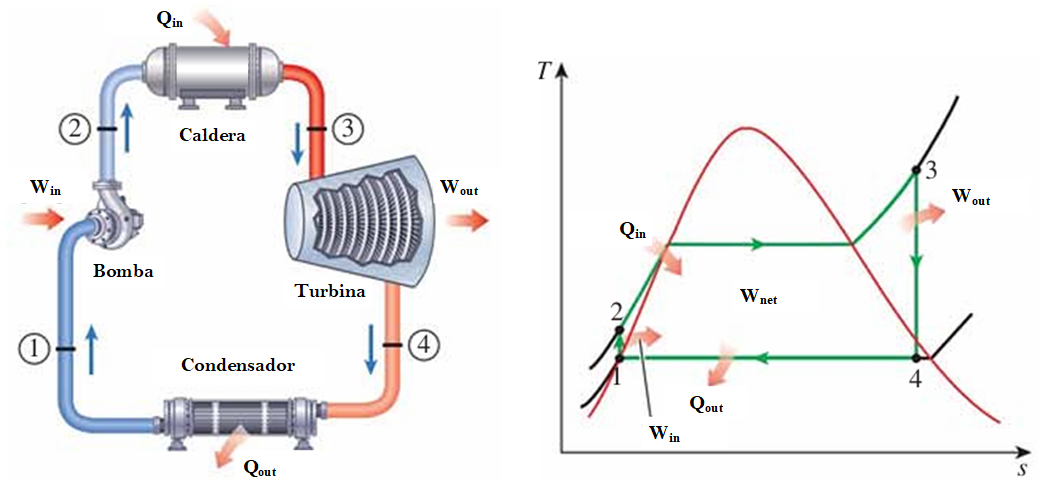

Figura 1. Diagrama y gráfica T-s de ciclo de Rankine simple ideal. Adaptado de Çengel et al. (2019).

A continuación, se resolverá un problema sobre este ciclo de potencia en MATLAB. Para facilitar la estimación de propiedades termodinámicas en entornos virtuales de MATLAB y en código, la autora implementa y comparte una función llamada `Coolpropgit`, la cual exporta los resultados de la versión en línea de `CoolProp` de `Python `([https://ibell.pythonanywhere.com/](https://ibell.pythonanywhere.com/)) a un `struct` que contiene el estado termodinámico estimado. 

Este problema es el Ejemplo 10-1 de Çengel et al. (2019): **Considere una central eléctrica de vapor de agua que opera con el ciclo Rankine ideal simple. El vapor entra en la turbina a 3 MPa y 350°C y se condensa en el condensador a una presión de 75 kPa. Determine la eficiencia térmica de este ciclo. **En el siguiente código se muestra la solución documentada al problema (da click al botón de "Ejecutar" para ver resultados):

true;
% Limpiar las variables del Workspace
clear all;

% Calcular los estados termodinámicos de cada etapa usando Coolpropgit
% En esta función se necesita saber el fluido y dos propiedades termodinámicas
% El estado 1 cuenta con dos propiedades termodinámicas conocidas: la
% presión y estar en líquido saturado (x=0)
estado1 = Coolpropgit("Water", "P", 75E3, "x", 0)

estado1 = struct with fields:
        T: 364.9080
        P: 7.5000e+04
        x: 0
        c: 1.5493e+03
        v: 0.0010
        h: 384.4374
        s: 1.2132
       Cp: 4.2070
       Cv: 3.8112
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


% El estado 2 está involucrado en un proceso isoentrópico con presión conocida
estado2 = Coolpropgit("Water", "P", 3E6, "s", estado1.s)

estado2 = struct with fields:
        T: 365.0935
        P: 3.0000e+06
        x: -1
        c: 1.5553e+03
        v: 0.0010
        h: 387.4694
        s: 1.2132
       Cp: 4.2006
       Cv: 3.8053
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


% El estado 3 cuenta con dos propiedades termodinámicas conocidas: la
% presión y temperatura
estado3 = Coolpropgit("Water", "P", 3E6, "T", 350+273.15)

estado3 = struct with fields:
        T: 623.1500
        P: 3.0000e+06
        x: -1
        c: 591.7739
        v: 0.0906
        h: 3.1161e+03
        s: 6.7449
       Cp: 2.3559
       Cv: 1.7202
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


% El estado 4 está involucrado en un proceso isoentrópico con presión conocida
estado4 = Coolpropgit("Water", "P", 75E3, "s", estado3.s)

estado4 = struct with fields:
        T: 364.9080
        P: 75000
        x: 0.8861
        c: NaN
        v: 1.9647
        h: 2.4030e+03
        s: 6.7449
       Cp: 2.0762
       Cv: 1.5545
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"



% Cálculo de transferencia energética: masa y calor
Win = estado2.h - estado1.h % [kJ/kg]

Win = 3.0320

Qin = estado3.h - estado2.h % [kJ/kg]

Qin = 2.7286e+03

Wout = estado3.h - estado4.h % [kJ/kg]

Wout = 713.0424

Qout = estado4.h - estado1.h % [kJ/kg]

Qout = 2.0186e+03

Wnet = Wout - Win % [kJ/kg]

Wnet = 710.0104


% Cálculo de la eficiencia térmica.
eta = Wnet / Qin

eta = 0.2602

**Es decir, esta central eléctrica convierte el 26% del calor que recibe en la caldera en trabajo neto. Una central eléctrica real que opere dentro de los mismos límites de temperatura y presión tendrá una menor eficiencia debido a irreversibilidades como la fricción.**

Para representar el proceso en un diagrama T-s, se implementa el siguiente código documentado. Es importante ejecutar el código de la sección anterior para emplear ciertos valores necesarios en el gráfico deseado (da click a "Graficar" para ver resultados):

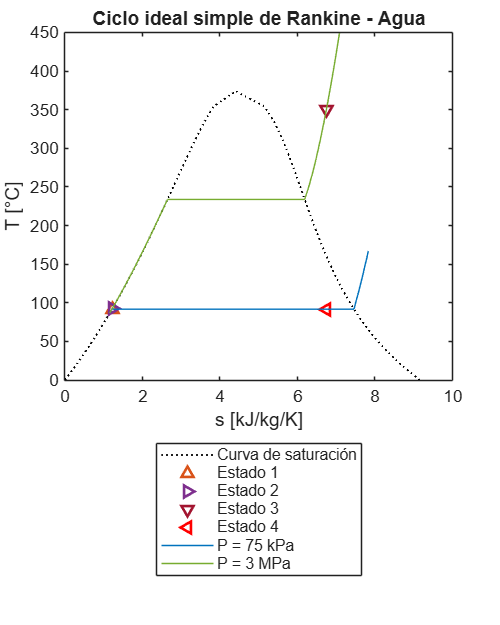

true;
% Curva de saturación
% Datos aproximados obtenidos de https://coolprop.org/fluid_properties/fluids/Water.html
Ttriple = 273.16; % [K] Temperatura triple
Tcritical = 647.096; % [K] Temperatura crítica
% Número de temperaturas a evaluar, entre mayor sea, más tardará el código
% pero la curva de saturación será más exacta
n = 20; 
% Temperaturas a evaluar
T = linspace(Ttriple, Tcritical, n); % [K]
% Arreglo de línea de saturación de líquido y vapor, respectivamente
sliquido = zeros(1, n); % [kJ/kg/K]
svapor = zeros(1, n); % [kJ/kg/K]
% Cálculo de entropía de saturación líquida y vapor por cada temperatura
for i = 1 : n
    sliquido(i) = Coolpropgit("Water", "T", T(i), "x", 0).s; % [kJ/kg/K]
    svapor(i) = Coolpropgit("Water", "T", T(i), "x", 1).s; % [kJ/kg/K]
end

% Isobara a 75 kPa
Pisobar1 = 75E3; % [Pa]
% Número de puntos de partes monofásicas, entre mayor sea, más tardará el código
% pero la curva de saturación será más exacta
n = 10;
% Entropía de líquido y vapor en saturación, respectivamente 
sliquid1 = Coolpropgit("Water", "P", Pisobar1, "x", 0).s; % [kJ/kg/K]
svapor1 = Coolpropgit("Water", "P", Pisobar1, "x", 1).s; % [kJ/kg/K]
% Arreglo de entropías: parte líquida + horizontal en saturación + parte vapor
sisobar1 = [linspace(sliquid1 * 0.95, sliquid1, n) linspace(svapor1, svapor1 * 1.05, n)]; % [kJ/kg/K]
% Arreglo de temperaturas correspondientes a cada entropía
Tisobar1 = zeros(1, 2 * n); % [K]
% Cálculo de temperatura para cada entropía
for i = 1 : 2 * n
    Tisobar1(i) = Coolpropgit("Water", "P", Pisobar1, "s", sisobar1(i)).T; % [K]
end

% Isobara a 3 MPa
Pisobar2 = 3E6; % [Pa]
% Número de puntos de partes monofásicas, entre mayor sea, más tardará el código
% pero la curva de saturación será más exacta
n = 10;
% Entropía de líquido y vapor en saturación, respectivamente 
sliquid2 = Coolpropgit("Water", "P", Pisobar2, "x", 0).s; % [kJ/kg/K]
svapor2 = Coolpropgit("Water", "P", Pisobar2, "x", 1).s; % [kJ/kg/K]
% Arreglo de entropías: parte líquida + horizontal en saturación + parte vapor
sisobar2 = [linspace(estado2. s* 0.95, sliquid2, n) linspace(svapor2, estado3.s * 1.05, n)]; % [kJ/kg/K]
% Arreglo de temperaturas correspondientes a cada entropía
Tisobar2 = zeros(1, 2 * n); % [K]
% Cálculo de temperatura para cada entropía
for i = 1 : 2 * n
    Tisobar2(i) = Coolpropgit("Water", "P", Pisobar2, "s", sisobar2(i)).T; % [K]
end

% Trazo de curvas
figure("Position", [100 100 400 500])
% Curva de saturación
sat = plot(sliquido, T - 273.15,":k", "LineWidth", 1); % Parte líquida
hold on; % Colocar múltiples curvas
plot(svapor, T - 273.15,":k", "LineWidth", 1); % Parte vapor
% Dibujar cada etapa del ciclo de Rankine simple
estado1Ts = plot(estado1.s, estado1.T - 273.15, "^", "Color", [0.8500 0.3250 0.0980], "LineWidth", 1.5);
estado2Ts = plot(estado2.s, estado2.T - 273.15, ">", "Color", [0.4940 0.1840 0.5560], "LineWidth", 1.5);
estado3Ts = plot(estado3.s, estado3.T - 273.15, "v", "Color", [0.6350 0.0780 0.1840], "LineWidth", 1.5);
estado4Ts = plot(estado4.s, estado4.T - 273.15, "<", "Color", "r", "LineWidth", 1.5);
% Dibujar cada isobara
isobar1 = plot(sisobar1, Tisobar1 - 273.15, "Color", [0 0.4470 0.7410]);
isobar2 = plot(sisobar2, Tisobar2 - 273.15, "Color", [0.4660 0.6740 0.1880]);
% Editar título de los ejes y de la gráfica
xlabel("s [kJ/kg/K]")
ylabel("T [°C]")
title("Ciclo ideal simple de Rankine - Agua")
% Editar leyenda
legend([sat, estado1Ts, estado2Ts, estado3Ts, estado4Ts, isobar1, isobar2], ...
    "Curva de saturación", "Estado 1", "Estado 2", "Estado 3", "Estado 4", "P = 75 kPa", "P = 3 MPa", ...
    "Location", "southoutside");

**Nota: Después que crear una figura y al hacer click encima de ella, al pasar el puntero del ratón por dentro del diagrama o por la parte superior derecha, podrás acceder a la configuración de la figura ** **. También en la parte superior derecha aparece el ícono ** ** para abrir la figura en una nueva ventana.**

### Ejercicio guiado 1: Efecto de la temperatura y presión

*Lecturas sugeridas: Sección 8.2.3 de Moran et al. (2018), sección 10-4 de Çengel et al. (2019) y sección 11.3 de Borgnakke y Sonntag (2020).*

Las plantas de generación eléctrica a vapor producen la mayor parte de la electricidad a nivel mundial, y hasta pequeñas mejoras en su eficiencia térmica representan un ahorro considerable en el uso de combustible o aprovechamiento de la fuente de calor. Por esta razón, se busca constantemente optimizar el ciclo de operación de estas centrales.

Hagamos un estudio preliminar del efecto de la temperatura y la presión en nuestro ciclo de potencia de interés. Para ello, resolvamos el Ejemplo 10-3 de Çengel et al. (2019): **Considere una central eléctrica de vapor de agua que opera según el ciclo Rankine ideal. El vapor entra en la turbina a 3 MPa y 350°C y se condensa en el condensador a una presión de 10 kPa (notemos que esto solo se diferencia del problema anterior por la presión del condensador). Determine (a) la eficiencia térmica de esta central, (b) la eficiencia térmica si el vapor se sobrecalienta a 600°C en lugar de 350°C, y (c) la eficiencia térmica si la presión de la caldera se eleva a 15 MPa mientras la temperatura de entrada de la turbina se mantiene a 600°C. **

La solución a este problema tiene una lógica similar al anterior. Para un análisis más amplio y didáctico, la temperatura del estado 3 y las dos presiones constantes características del ciclo se alterarán mediante controles Sliders. Esto permite intectuar con estas propiedades y hacer un análisis a diferentes condiciones. En el siguiente código se muestra la solución documentada al problema (modifica los Sliders y da click a "Ejecutar" para ver resultados):

false;
% Limpiar las variables del Workspace
clear all;

Pisobar1 = 10000% [Pa], para (a), (b) y (c) vale 10E3. En el problema anterior es 75E3

Pisobar1 = 10000

Pisobar2 = 15000000% [Pa], para (a) y (b) vale 3E6, para (c) 15E6. En el problema anterior es 3E6

Pisobar2 = 15000000

T3 = 600; % [K], para (b) y (c) vale 600, para (a) 350. En el problema anterior es 350

% Obtención de estados por cada etapa
% Presión conocida en líquido saturado
estado1 = Coolpropgit("Water", "P", Pisobar1, "x", 0)

estado1 = struct with fields:
        T: 318.9563
        P: 1.0000e+04
        x: 0
        c: 1.5374e+03
        v: 0.0010
        h: 191.8059
        s: 0.6492
       Cp: 4.1805
       Cv: 4.0466
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


% Proceso isoentrópico en bomba
estado2 = Coolpropgit("Water", "P", Pisobar2, "s", estado1.s)

estado2 = struct with fields:
        T: 319.4545
        P: 1.5000e+07
        x: -1
        c: 1.5644e+03
        v: 0.0010
        h: 206.9022
        s: 0.6492
       Cp: 4.1468
       Cv: 4.0056
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


% Presión y Temperatura conocidas en estado 3
estado3 = Coolpropgit("Water", "P", Pisobar2, "T", T3 + 273.15)

estado3 = struct with fields:
        T: 873.1500
        P: 1.5000e+07
        x: -1
        c: 691.1623
        v: 0.0249
        h: 3.5831e+03
        s: 6.6796
       Cp: 2.6098
       Cv: 1.8897
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


% Proceso isoentrópico en turbina
estado4 = Coolpropgit("Water", "P", Pisobar1, "s", estado3.s)

estado4 = struct with fields:
        T: 318.9563
        P: 10000
        x: 0.8041
        c: NaN
        v: 11.7963
        h: 2.1152e+03
        s: 6.6796
       Cp: 1.9681
       Cv: 1.4840
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"



% Cálculo de transferencia energética: masa y calor
Win = estado2.h - estado1.h % [kJ/kg]

Win = 15.0962

Qin = estado3.h - estado2.h % [kJ/kg]

Qin = 3.3762e+03

Wout = estado3.h - estado4.h % [kJ/kg]

Wout = 1.4679e+03

Qout = estado4.h - estado1.h % [kJ/kg]

Qout = 1.9234e+03

Wnet = Wout - Win % [kJ/kg]

Wnet = 1.4528e+03


% Cálculo de la eficiencia térmica
eta = Wnet / Qin

eta = 0.4303

**(a) La eficiencia térmica aumenta del 26.0% (esto del Ejemplo 10-1 de Çengel et al., 2019) al 33.4% al reducir la presión del condensador de 75 a 10 kPa. Al mismo tiempo, sin embargo, la calidad del vapor disminuye del 88.6% al 81.3% (es decir, el contenido de humedad aumenta del 11.4% al 18.7%). **

**(b) La eficiencia térmica aumenta del 33.4% al 37.3% al sobrecalentar el vapor de 350°C a 600°C. Al mismo tiempo, la calidad del vapor aumenta del 81.3% al 91.5% (es decir, el contenido de humedad disminuye del 18.7% al 8.5%).**

**(c) La eficiencia térmica aumenta del 37.3% al 43.0% al aumentar la presión de la caldera de 3 a 15 MPa, manteniendo la temperatura de entrada de la turbina a 600°C. Al mismo tiempo, sin embargo, la calidad del vapor disminuye del 91.5 % al 80.4% (es decir, el contenido de humedad aumenta del 8.5% al 19.6%).**

***¿Por qué estos cambios aumentan la eficiencia térmica? ¿Existen otras modificaciones que mejoren la eficiencia térmica? ¿Cómo afecta (positiva o negativamente) el contenido de humedad a la salida de la turbina? Investiga y discute con tus compañeros y profesor. Al inicio de esta subsección se encuentran lecturas sugeridas para contestar estas preguntas, pero se invita al estudiante a también investigar en otras fuentes académicas y científicas para enriquecer su conocimiento.***

También se puede visualizar el diagrama T-s, Para ello, se implementa el siguiente código documentado. Es importante ejecutar el código de la sección anterior para emplear ciertos valores necesarios en el gráfico deseado (da click a "Graficar" para ver resultados):

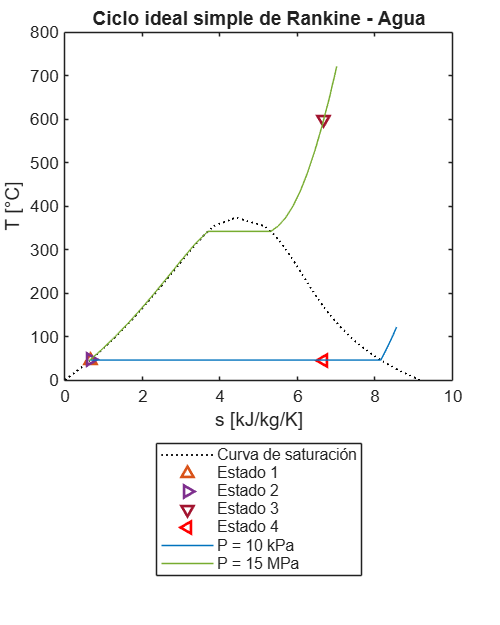

false;
% Curva de saturación
Ttriple = 273.16; % [K]
Tcritical = 647.096; % [K] 
n = 20;
T = linspace(Ttriple, Tcritical, n); % [K]
sliquido = zeros(1, n); % [kJ/kg/K]
svapor = zeros(1, n); % [kJ/kg/K]
for i = 1 : n
    sliquido(i) = Coolpropgit("Water", "T", T(i), "x", 0).s; % [kJ/kg/K]
    svapor(i) = Coolpropgit("Water", "T", T(i), "x", 1).s; % [kJ/kg/K]
end

% Isobara con P = Pisobar1
n = 10;
sliquid1 = Coolpropgit("Water", "P", Pisobar1, "x", 0).s; % [kJ/kg/K]
svapor1 = Coolpropgit("Water", "P", Pisobar1, "x", 1).s; % [kJ/kg/K]
sisobar1 = [linspace(sliquid1 * 0.95, sliquid1, n) linspace(svapor1, svapor1 * 1.05, n)]; % [kJ/kg/K]
Tisobar1 = zeros(1, 2 * n); % [K]
for i = 1 : 2 * n
    Tisobar1(i) = Coolpropgit("Water", "P", Pisobar1, "s", sisobar1(i)).T; % [K]
end

% Isobara con P = Pisobar2
n = 10;
sliquid2 = Coolpropgit("Water", "P", Pisobar2, "x", 0).s; % [kJ/kg/K]
svapor2 = Coolpropgit("Water", "P", Pisobar2, "x", 1).s; % [kJ/kg/K]
sisobar2 = [linspace(estado2.s * 0.95, sliquid2, n) linspace(svapor2, estado3.s * 1.05, n)]; % [kJ/kg/K]
Tisobar2 = zeros(1, 2 * n); % [K]
for i = 1 : 2 * n
    Tisobar2(i) = Coolpropgit("Water", "P", Pisobar2, "s", sisobar2(i)).T; % [K]
end

% Trazo de curvas
figure("Position", [100 100 400 500]) 
sat = plot(sliquido, T - 273.15, ":k", "LineWidth", 1);
hold on;
plot(svapor, T - 273.15, ":k", "LineWidth", 1);
estado1Ts = plot(estado1.s, estado1.T - 273.15, "^", "Color", [0.8500 0.3250 0.0980], "LineWidth", 1.5);
estado2Ts = plot(estado2.s, estado2.T - 273.15, ">", "Color", [0.4940 0.1840 0.5560], "LineWidth", 1.5);
estado3Ts = plot(estado3.s, estado3.T - 273.15, "v", "Color", [0.6350 0.0780 0.1840], "LineWidth", 1.5);
estado4Ts = plot(estado4.s, estado4.T - 273.15, "<", "Color", "r", "LineWidth", 1.5);
isobar1 = plot(sisobar1, Tisobar1 - 273.15, "Color", [0 0.4470 0.7410]);
isobar2 = plot(sisobar2, Tisobar2 - 273.15, "Color", [0.4660 0.6740 0.1880]);
xlabel("s [kJ/kg/K]")
ylabel("T [°C]")
title("Ciclo ideal simple de Rankine - Agua")
legend([sat, estado1Ts, estado2Ts, estado3Ts, estado4Ts, isobar1, isobar2], ...
    "Curva de saturación", "Estado 1", "Estado 2", "Estado 3", "Estado 4", ...
    "P = " + num2str(Pisobar1 * 1E-3) + " kPa", "P = " + num2str(Pisobar2 * 1E-6) + " MPa", ...
    "Location", "southoutside");

### Ejercicio guiado 2: Efecto del fluido de trabajo

*Lecturas sugeridas: Secciones 1.2 a 1.6 de Macchi y Astolfi (2017) y secciones 1.2 a 1.5 de Tarrad (2022).*

La selección del fluido de trabajo en un ciclo de Rankine juega un papel crucial para la eficiencia térmica, la potencia neta de salida y la capacidad de absorción de energía. Además, la arquitectura y la disposición del ciclo; el tamaño, el tipo y la forma de los componentes; y la rentabilidad del funcionamiento dependen en gran medida de las propiedades termofísicas y de la estabilidad química del fluido de trabajo. 

Hagamos un estudio preliminar del fluido de trabajo en nuestro ciclo de potencia de interés. Para ello, resolvamos los Ejercicios 11.21-11.23 de Borgnakke y Sonntag (2020): **Se utilizará agua caliente geotérmica como fuente de energía en un ciclo Rankine ideal, con R-134a como fluido de trabajo. El vapor saturado de R-134a sale de la caldera a una temperatura de 85°C y la temperatura del condensador es de 40°C. (a) Calcule la eficiencia térmica de este ciclo. (b) Repite el ejercicio con R-410a como fluido de trabajo. (c) Repite el ejercicio con amoníaco como fluido de trabajo. **

La solución a este problema tiene una lógica similar a los anteriores. Para un análisis más didáctico, el fluido de trabajo puede seleccionarse mendiante un control Drop Down. Esto permite intectuar con esta propiedad y hacer un análisis a diferentes condiciones. En el siguiente código se muestra la solución documentada al problema (modifica el Drop Down y da click a "Ejecutar" para ver resultados):

true;
% Limpiar las variables del Workspace
clear all;

% Selección de fluido de trabajo
fluido = "Ammonia"; % (a) R134a, (b) R410A, (c) Ammonia

% Obtención de estados por cada etapa
% Temperatura conocida en vapor saturado
estado3 = Coolpropgit(fluido, "T", 85 + 273.15, "x", 1)

estado3 = struct with fields:
        T: 358.1500
        P: 4.6095e+06
        x: 1
        c: 382.6675
        v: 0.0261
        h: 1.6134e+03
        s: 5.1628
       Cp: 5.7984
       Cv: 2.8112
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


% Temperatura conocida en líquido saturado
estado1 = Coolpropgit(fluido, "T", 40 + 273.15, "x", 0)

estado1 = struct with fields:
        T: 313.1500
        P: 1.5545e+06
        x: 0
        c: 1.2239e+03
        v: 0.0017
        h: 536.1213
        s: 2.1274
       Cp: 4.9333
       Cv: 2.7604
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


% Proceso isoentrópico en turbina
estado4 = Coolpropgit(fluido, "P", estado1.P, "s", estado3.s)

estado4 = struct with fields:
        T: 313.1500
        P: 1.5545e+06
        x: 0.8644
        c: NaN
        v: 0.0721
        h: 1.4867e+03
        s: 5.1628
       Cp: 3.8329
       Cv: 2.4063
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


% Proceso isoentrópico en bomba
estado2 = Coolpropgit(fluido, "P", estado3.P, "s", estado1.s)

estado2 = struct with fields:
        T: 314.1018
        P: 4.6095e+06
        x: -1
        c: 1.2429e+03
        v: 0.0017
        h: 541.3829
        s: 2.1274
       Cp: 4.8881
       Cv: 2.7589
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"



Win = estado2.h - estado1.h % [kJ/kg]

Win = 5.2616

Qin = estado3.h - estado2.h % [kJ/kg]

Qin = 1.0720e+03

Wout = estado3.h - estado4.h % [kJ/kg]

Wout = 126.7358

Qout = estado4.h - estado1.h % [kJ/kg]

Qout = 950.5418

Wnet = Wout - Win % [kJ/kg]

Wnet = 121.4742

eta = Wnet / Qin

eta = 0.1133

**(a) Se obtiene una eficiencia térmica del 10.19%.**

**(b) No fue posible calcular la eficiencia térmica bajo las condiciones del problema.***** ¿Por qué? ¿Qué propiedades o características del fluido de trabajo no permiten seleccionar esta sustancia para la operación del ciclo de Rankine planteado en el problema? Analiza, investiga y discute con tus compañeros y profesor.***

**(c) Se obtiene una eficiencia térmica del 11.33%. *****¿Por qué este aumento respecto al primer inciso? ¿Qué propiedades o características del fluido de trabajo influyen en esto? Analiza, investiga y discute con tus compañeros y profesor.***

***¿Qué aspectos deben considerarse (no solo operacionales o propiedades de la sustancia, pueden ser de seguridad, ambientales, económicos, ...) para escoger el fluido de trabajo? Investiga y discute con tus compañeros y profesor. Al inicio de esta subsección se encuentran lecturas sugeridas para contestar todas estas preguntas, pero se invita al estudiante a también investigar en otras fuentes académicas y científicas para enriquecer su conocimiento.***

También se puede visualizar el diagrama T-s, Para ello, se implementa el siguiente código documentado. Es importante ejecutar el código de la sección anterior para emplear ciertos valores necesarios en el gráfico deseado (da click a "Graficar" para ver resultados). ***¿Observas alguna diferencia en las curvas trazadas para el agua en problemas anteriores y entre los fluidos de trabajo del problema actual? Analiza y discute con tus compañeros y profesor***: 

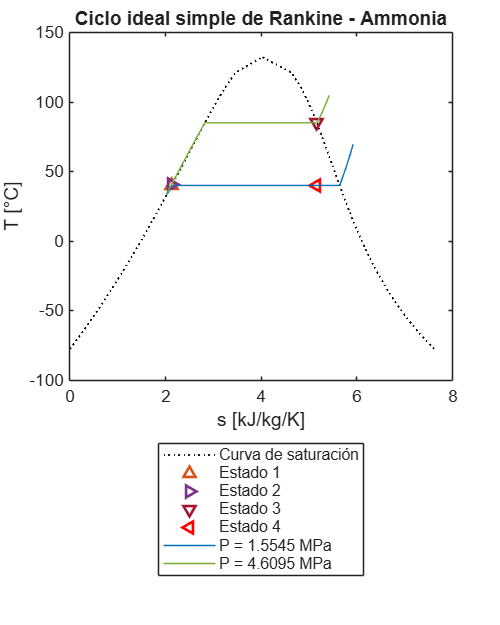

true;
% Curva de saturación
% Temperatura triple y crítica dependiendo del fluido de trabajo
% (a) R134a - Ttriple ≈ 169.85 K, Tcritical ≈ 374.21 K https://coolprop.org/fluid_properties/fluids/R134a.html
% (b) R410A - Ttriple ≈ 200 K, Tcritical ≈ 344.49 K https://coolprop.org/fluid_properties/fluids/R410A.html
% (c) Ammonia - Ttriple ≈ 195.495 K, Tcritical ≈ 405.4 K https://coolprop.org/fluid_properties/fluids/Ammonia.html
if fluido == "R134a"
    Ttriple = 169.85; % [K] 
    Tcritical = 374.21; % [K] 
elseif fluido == "R410A"
    Ttriple = 200; % [K] 
    Tcritical = 344.49; % [K] 
else
    Ttriple = 195.495; % [K] 
    Tcritical = 405.4; % [K] 
end
n = 20;
T = linspace(Ttriple, Tcritical, n); % [K]
sliquido = zeros(1, n); % [kJ/kg/K]
svapor = zeros(1, n); % [kJ/kg/K]
for i = 1 : n
    sliquido(i) = Coolpropgit(fluido, "T", T(i), "x", 0).s; % [kJ/kg/K]
    svapor(i) = Coolpropgit(fluido, "T", T(i), "x", 1).s; % [kJ/kg/K]
end

% Calcular isobaras para (a) y (c)
if fluido ~= "R410A"
    Pisobar1 = estado1.P; % [Pa]
    n = 10;
    sliquid1 = Coolpropgit(fluido, "P", Pisobar1, "x", 0).s; % [kJ/kg/K]
    svapor1 = Coolpropgit(fluido, "P", Pisobar1, "x", 1).s; % [kJ/kg/K]
    sisobar1 = [linspace(sliquid1 * 0.95, sliquid1, n) linspace(svapor1, svapor1 * 1.05, n)]; % [kJ/kg/K]
    Tisobar1 = zeros(1, 2 * n); % [K]
    for i = 1 : 2 * n
        Tisobar1(i) = Coolpropgit(fluido, "P", Pisobar1, "s", sisobar1(i)).T; % [K]
    end
    
    Pisobar2 = estado3.P; % [Pa]
    n = 10;
    sliquid2 = Coolpropgit(fluido, "P", Pisobar2, "x", 0).s; % [kJ/kg/K]
    svapor2 = Coolpropgit(fluido, "P", Pisobar2, "x", 1).s; % [kJ/kg/K]
    sisobar2 = [linspace(estado2.s * 0.95, sliquid2, n) linspace(svapor2, estado3.s * 1.05, n)]; % [kJ/kg/K]
    Tisobar2 = zeros(1, 2 * n); % [K]
    for i = 1 : 2 * n
        Tisobar2(i) = Coolpropgit(fluido, "P", Pisobar2, "s", sisobar2(i)).T; % [K]
    end
end

% Trazo de curvas
% Curva de saturación para todos los incisos
figure("Position", [100 100 400 500]) 
sat = plot(sliquido, T - 273.15, ":k", "LineWidth", 1);
hold on;
plot(svapor, T - 273.15, ":k", "LineWidth", 1);
% Isobaras y estados para (a) y (c)
if fluido ~= "R410A"
    estado1Ts = plot(estado1.s, estado1.T - 273.15, "^", "Color", [0.8500 0.3250 0.0980], "LineWidth", 1.5);
    estado2Ts = plot(estado2.s, estado2.T - 273.15, ">", "Color", [0.4940 0.1840 0.5560], "LineWidth", 1.5);
    estado3Ts = plot(estado3.s, estado3.T - 273.15, "v", "Color", [0.6350 0.0780 0.1840], "LineWidth", 1.5);
    estado4Ts = plot(estado4.s, estado4.T - 273.15, "<", "Color", "r", "LineWidth", 1.5);
    isobar1 = plot(sisobar1, Tisobar1 - 273.15, "Color", [0 0.4470 0.7410]);
    isobar2 = plot(sisobar2, Tisobar2 - 273.15, "Color", [0.4660 0.6740 0.1880]);
    % Leyenda de todas las curvas
    legend([sat, estado1Ts, estado2Ts, estado3Ts, estado4Ts, isobar1, isobar2], ...
        "Curva de saturación", "Estado 1", "Estado 2", "Estado 3", "Estado 4", ...
        "P = "+ num2str(Pisobar1 * 1E-6) +" MPa", "P = "+ num2str(Pisobar2 * 1E-6) + " MPa", ...
        "Location", "southoutside");
% Solo curva de saturación de (b)
else
    % Leyenda solo de la curva de saturación
    legend([sat], "Curva de saturación", "Location", "southoutside");
end
% Editar título de los ejes y de la gráfica
xlabel("s [kJ/kg/K]")
ylabel("T [°C]")
title("Ciclo ideal simple de Rankine - " + fluido)

### Ejercicio guiado 3: Efecto de irreversibilidades

*Lecturas sugeridas: Sección 8.2.4 de Moran et al. (2018), sección 10-3 de Çengel et al. (2019) y sección 11.6 de Borgnakke y Sonntag (2020).*

Este ciclo de potencia en la realidad difiere de lo ideal debido a las irreversibilidades de varios componentes. La fricción del fluido (generando caídas de presión en los intercambiadores de calor y tuberías), la pérdida de calor al entorno y con relación al trabajo en la turbina (genera menor trabajo a lo ideal) y bomba (requiere mayor trabajo a lo ideal) son fuentes comunes de irreversibilidad (Figura 2). La última causa se vincula a la definición de eficiencia isoentrópica en estos dos dispositivos, donde los estados 2a y 4a son los estados de salida reales de la bomba y la turbina, respectivamente, y 2s y 4s son los estados correspondientes para el caso isentrópico ideal (Figura 3):

$\eta_{Bomba}=\frac{h_{2s}-h_{1}}{h_{2a}-h_{1}}$, $\eta_{Turbina}=\frac{h_{3}-h_{4a}}{h_{3}-h_{4s}}$

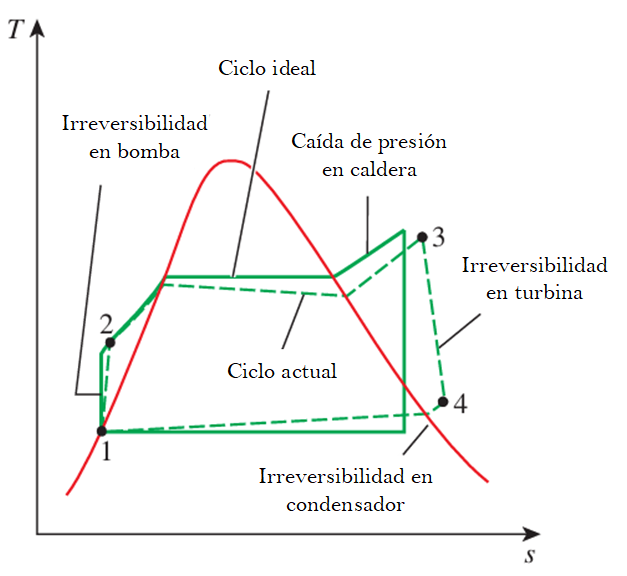

Figura 2. Desviación del ciclo de potencia de vapor real respecto del ciclo Rankine ideal. Adaptado de Çengel et al. (2019).

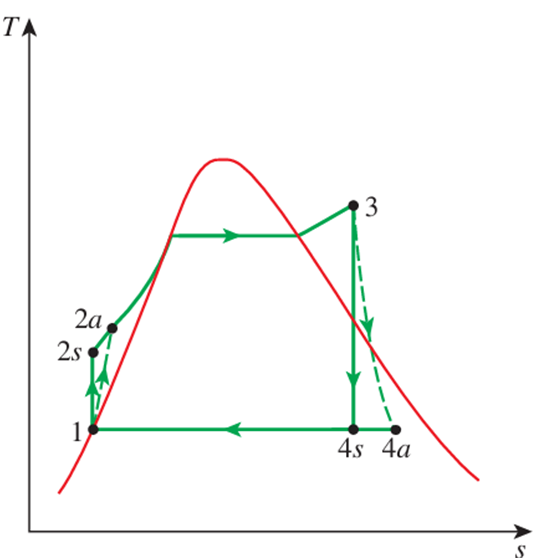

Figura 3. Efecto de las irreversibilidades de las bombas y turbinas en el ciclo Rankine ideal. Adaptado de Çengel et al. (2019).

***Pero, ¿Por qué ocurren todas estas irreversibilidades? ¿Existen otras causas (internas o externas al ciclo termodinámico) de irreversibilidades? Investiga y discute con tus compañeros y profesor. Al inicio de esta subsección se encuentran lecturas sugeridas para contestar todas estas preguntas, pero se invita al estudiante a también investigar en otras fuentes académicas y científicas para enriquecer su conocimiento.***

Por ahora, vamos a resolver un problema para ver el efecto de las irreversibilidades en la eficiencia térmica de un ciclo de Rankine simple. Para ello, tomaremos el Ejemplo 10-2 de Çengel et al. (2019): **Una central eléctrica de vapor opera según el ciclo que se muestra en la Figura 4. Si la eficiencia isentrópica de la turbina es del 87% y la eficiencia isentrópica de la bomba es del 85%, determine la eficiencia térmica del ciclo. Notemos que el inciso (c) del la subsección "Ejercicio guiado 1: Efecto de la temperatura y presión" representa este ciclo sin irreversibilidades (ideal),**

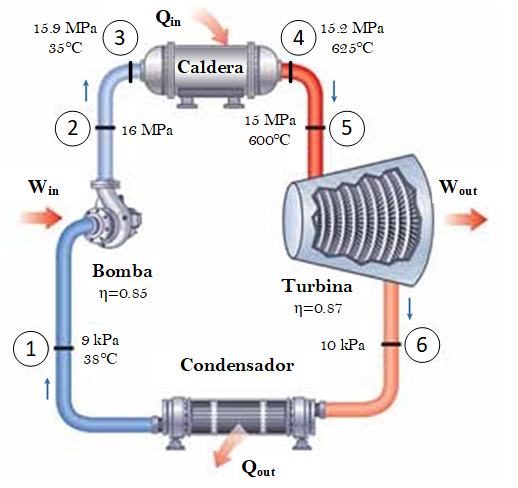

Figura 4. Diagrama adaptado del ciclo de Rankine simple real del Ejemplo 10-2 de Çengel et al. (2019).

La solución a este problema tiene una lógica similar a los anteriores. Para un análisis más didáctico, ciertas temperaturas, presiones y eficiencias isoentrópicas se alterarán mediante controles Sliders. Esto permite intectuar con estas propiedades y hacer un análisis a diferentes condiciones. En el siguiente código se muestra la solución documentada al problema (modifica los Sliders y da click a "Ejecutar" para ver resultados):

false;
% Limpiar las variables del Workspace
clear all;

etabomba = 0.85; % para este problema vale 0.85, para replicar (c) de la subsección Ejercicio guiado 1, vale 1
etaturbina = 0.87; % para este problema vale 0.87, para replicar (c) de la subsección Ejercicio guiado 1, vale 1
% P6 > P1 por caída de presión en condensador
P1 = 9000; % [Pa], para este problema vale 9E3, para replicar (c) de la subsección Ejercicio guiado 1, vale 10E3
P6 = 10E3; % [Pa]
% P2 > P3 > P4 > P5 por caídas de presión en tuberías y caldera
P2 = 16000000; % [Pa], para este problema vale 15.2E6, para replicar (c) de la subsección Ejercicio guiado 1, vale 15E6
P3 = 15900000; % [Pa], para este problema vale 15.9E6, para replicar (c) de la subsección Ejercicio guiado 1, vale 15E6
P4 = 15200000; % [Pa], para este problema vale 15.2E6, para replicar (c) de la subsección Ejercicio guiado 1, vale 15E6
P5 = 15E6; % [Pa]
% Pérdida de calor del fluido a la salida del condensador
T1 = 38; % [°C], para este problema vale 38, para replicar (c) de la subsección Ejercicio guiado 1, vale ≈ 45.8063 (temperatura de líquido saturado a P6)
% Pérdida de calor del fluido a la entrada de la caldera
T3 = 35; % [°C], para este problema vale 35, para replicar (c) de la subsección Ejercicio guiado 1, vale ≈ 46.3045 (temperatura del estado 2 de (c) de la subsección Ejercicio guiado 1)
% Sobrecalentamiento de la caldera respecto a (c) de la subsección Ejercicio guiado 1
T4 =  625; % [°C], para este problema vale 625, para replicar (c) de la subsección Ejercicio guiado 1, vale 600
T5 = 600; % [°C]
estado1 = Coolpropgit("Water", "P", P1, "T", T1 + 273.15)

estado1 = struct with fields:
        T: 311.1500
        P: 9.0000e+03
        x: -1
        c: 1.5253e+03
        v: 0.0010
        h: 159.1753
        s: 0.5456
       Cp: 4.1795
       Cv: 4.0827
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


estado2s = Coolpropgit("Water", "P", P2, "s", estado1.s)

estado2s = struct with fields:
        T: 311.6000
        P: 1.6000e+07
        x: -1
        c: 1.5537e+03
        v: 0.0010
        h: 175.2255
        s: 0.5456
       Cp: 4.1416
       Cv: 4.0361
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


estado2 = Coolpropgit("Water", "P", P2, "h", (estado2s.h - estado1.h) / etabomba + estado1.h)

estado2 = struct with fields:
        T: 312.2839
        P: 1.6000e+07
        x: -1
        c: 1.5549e+03
        v: 0.0010
        h: 178.0578
        s: 0.5547
       Cp: 4.1418
       Cv: 4.0333
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


estado3 = Coolpropgit("Water", "P", P3, "T", T3 + 273.15)

estado3 = struct with fields:
        T: 308.1500
        P: 1.5900e+07
        x: -1
        c: 1.5469e+03
        v: 9.9910e-04
        h: 160.8499
        s: 0.4996
       Cp: 4.1406
       Cv: 4.0501
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


estado4 = Coolpropgit("Water", "P", P4, "T", T4 + 273.15)

estado4 = struct with fields:
        T: 898.1500
        P: 1.5200e+07
        x: -1
        c: 703.3971
        v: 0.0255
        h: 3.6464e+03
        s: 6.7453
       Cp: 2.5840
       Cv: 1.8908
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


estado5 = Coolpropgit("Water", "P", P5, "T", T5 + 273.15)

estado5 = struct with fields:
        T: 873.1500
        P: 1.5000e+07
        x: -1
        c: 691.1623
        v: 0.0249
        h: 3.5831e+03
        s: 6.6796
       Cp: 2.6098
       Cv: 1.8897
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


estado6s = Coolpropgit("Water", "P", P6, "s", estado5.s)

estado6s = struct with fields:
        T: 318.9563
        P: 10000
        x: 0.8041
        c: NaN
        v: 11.7963
        h: 2.1152e+03
        s: 6.6796
       Cp: 1.9681
       Cv: 1.4840
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"


estado6 = Coolpropgit("Water", "P", P6, "h", estado5.h - etaturbina * (estado5.h - estado6s.h))

estado6 = struct with fields:
        T: 318.9563
        P: 10000
        x: 0.8839
        c: NaN
        v: 12.9666
        h: 2.3061e+03
        s: 7.2779
       Cp: 1.9544
       Cv: 1.4729
    units: "T [K], P [Pa], x [kg/kg], c [m/s], v [m^3/kg], h [kJ/kg], s [kJ/kg/K], Cp [kJ/kg/K], Cv [kJ/kg/K]"



Win = estado2.h - estado1.h % [kJ/kg]

Win = 18.8825

Qin = estado4.h - estado3.h % [kJ/kg]

Qin = 3.4855e+03

Wout = estado5.h - estado6.h % [kJ/kg]

Wout = 1.2771e+03

Qout = estado6.h - estado1.h % [kJ/kg]

Qout = 2.1469e+03

Wnet = Wout - Win % [kJ/kg]

Wnet = 1.2582e+03

eta = Wnet / Qin

eta = 0.3610

**Con irreversibilidades, el ciclo redujo su eficiencia térmica de 43% ((c) de la subsección Ejercicio guiado 1) a 36.1%.**

También se puede visualizar el diagrama T-s, Para ello, se implementa el siguiente código documentado. Es importante ejecutar el código de la sección anterior para emplear ciertos valores necesarios en el gráfico deseado (da click a "Graficar" para ver resultados):

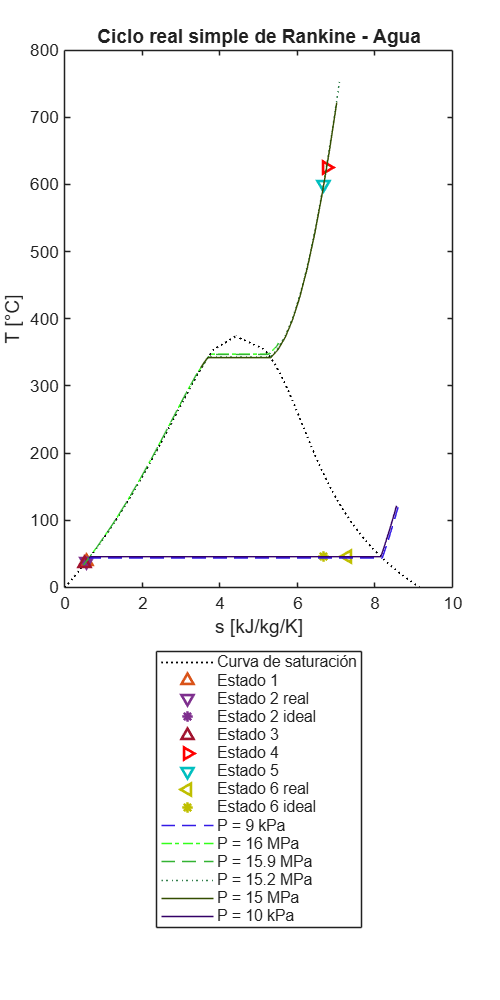

true;
% Curva de saturación
Ttriple = 273.16; % [K]
Tcritical = 647.096; % [K] 
n = 20;
T = linspace(Ttriple, Tcritical, n); % [K]
sliquido = zeros(1, n); % [kJ/kg/K]
svapor = zeros(1, n); % [kJ/kg/K]
for i = 1 : n
    sliquido(i) = Coolpropgit("Water", "T", T(i), "x", 0).s; % [kJ/kg/K]
    svapor(i) = Coolpropgit("Water", "T", T(i), "x", 1).s; % [kJ/kg/K]
end

% Isobara con P = P1
n = 10;
sliquid1 = Coolpropgit("Water", "P", P1, "x", 0).s; % [kJ/kg/K]
svapor1 = Coolpropgit("Water", "P", P1, "x", 1).s; % [kJ/kg/K]
sisobar1 = [linspace(sliquid1 * 0.95, sliquid1, n) linspace(svapor1, svapor1 * 1.05, n)]; % [kJ/kg/K]
Tisobar1 = zeros(1, 2 * n); % [K]
for i = 1 : 2 * n
    Tisobar1(i) = Coolpropgit("Water", "P", P1, "s", sisobar1(i)).T; % [K]
end

% Isobara con P = P2
n = 10;
sliquid2 = Coolpropgit("Water", "P", P2, "x", 0).s; % [kJ/kg/K]
svapor2 = Coolpropgit("Water", "P", P2, "x", 1).s; % [kJ/kg/K]
sisobar2 = [linspace(estado2s.s * 0.95, sliquid2, n) linspace(svapor2, svapor2 * 1.05, n)]; % [kJ/kg/K]
Tisobar2 = zeros(1, 2 * n); % [K]
for i = 1 : 2 * n
    Tisobar2(i) = Coolpropgit("Water", "P", P2, "s", sisobar2(i)).T; % [K]
end

% Isobara con P = P3
n = 10;
sliquid3 = Coolpropgit("Water", "P", P3, "x", 0).s; % [kJ/kg/K]
svapor3 = Coolpropgit("Water", "P", P3, "x", 1).s; % [kJ/kg/K]
sisobar3 = [linspace(estado3.s * 0.95, sliquid3, n) linspace(svapor3, svapor3 * 1.05, n)]; % [kJ/kg/K]
Tisobar3 = zeros(1, 2 * n); % [K]
for i = 1 : 2 * n
    Tisobar3(i) = Coolpropgit("Water", "P", P3, "s", sisobar3(i)).T; % [K]
end

% Isobara con P = P4
n = 10;
sliquid4 = Coolpropgit("Water", "P", P4, "x", 0).s; % [kJ/kg/K]
svapor4 = Coolpropgit("Water", "P", P4, "x", 1).s; % [kJ/kg/K]
sisobar4 = [linspace(sliquid4 * 0.95, sliquid4, n) linspace(svapor4, estado4.s * 1.05, n)]; % [kJ/kg/K]
Tisobar4 = zeros(1, 2 * n); % [K]
for i = 1 : 2 * n
    Tisobar4(i) = Coolpropgit("Water", "P", P4, "s", sisobar4(i)).T; % [K]
end

% Isobara con P = P5
n = 10;
sliquid5 = Coolpropgit("Water", "P", P5, "x", 0).s; % [kJ/kg/K]
svapor5 = Coolpropgit("Water", "P", P5, "x", 1).s; % [kJ/kg/K]
sisobar5 = [linspace(sliquid5 * 0.95, sliquid5, n) linspace(svapor5, estado5.s * 1.05, n)]; % [kJ/kg/K]
Tisobar5 = zeros(1, 2 * n); % [K]
for i = 1 : 2 * n
    Tisobar5(i) = Coolpropgit("Water", "P", P5, "s", sisobar5(i)).T; % [K]
end

% Isobara con P = P6
n = 10;
sliquid6 = Coolpropgit("Water", "P", P6, "x", 0).s; % [kJ/kg/K]
svapor6 = Coolpropgit("Water", "P", P6, "x", 1).s; % [kJ/kg/K]
sisobar6 = [linspace(sliquid6 * 0.95, sliquid6, n) linspace(svapor6, svapor6 * 1.05, n)]; % [kJ/kg/K]
Tisobar6 = zeros(1, 2 * n); % [K]
for i = 1 : 2 * n
    Tisobar6(i) = Coolpropgit("Water", "P", P6, "s", sisobar6(i)).T; % [K]
end

% Trazo de curvas
figure("Position", [100 100 400 800]) 
sat = plot(sliquido, T - 273.15, ":k", "LineWidth", 1);
hold on;
plot(svapor, T - 273.15, ":k", "LineWidth", 1);
estado1Ts = plot(estado1.s, estado1.T - 273.15, "^", "Color", [0.8500 0.3250 0.0980], "LineWidth", 1.5);
estado2Ts = plot(estado2.s, estado2.T - 273.15, "v", "Color", [0.4940 0.1840 0.5560], "LineWidth", 1.5);
estado2sTs = plot(estado2s.s, estado2s.T - 273.15, "*", "Color", [0.4940 0.1840 0.5560], "LineWidth", 1.5);
estado3Ts = plot(estado3.s, estado3.T - 273.15, "^", "Color", [0.6350 0.0780 0.1840], "LineWidth", 1.5);
estado4Ts = plot(estado4.s, estado4.T - 273.15, ">", "Color", "r", "LineWidth", 1.5);
estado5Ts = plot(estado5.s, estado5.T - 273.15, "v", "Color", [0, 0.75, 0.75], "LineWidth", 1.5);
estado6Ts = plot(estado6.s, estado6.T - 273.15, "<", "Color", [0.75, 0.75, 0], "LineWidth", 1.5);
estado6sTs = plot(estado6s.s, estado6s.T - 273.15, "*", "Color", [0.75, 0.75, 0], "LineWidth", 1.5);
isobar1 = plot(sisobar1, Tisobar1 - 273.15, "Color", [0.2 0.1 0.9], "LineStyle", "--");
isobar2 = plot(sisobar2, Tisobar2 - 273.15, "Color", [0.2 1 0.1], "LineStyle", "-.");
isobar3 = plot(sisobar3, Tisobar3 - 273.15, "Color", [0.2 0.7 0.2], "LineStyle", "--");
isobar4 = plot(sisobar4, Tisobar4 - 273.15, "Color", [0.2 0.5 0.3], "LineStyle", ":");
isobar5 = plot(sisobar5, Tisobar5 - 273.15, "Color", [0.2 0.3 0]);
isobar6 = plot(sisobar6, Tisobar6 - 273.15, "Color", [0.2 0 0.4]);
xlabel("s [kJ/kg/K]")
ylabel("T [°C]")
title("Ciclo real simple de Rankine - Agua")
legend([sat, estado1Ts, estado2Ts, estado2sTs, estado3Ts, estado4Ts, estado5Ts, estado6Ts, ...
    estado6sTs, isobar1, isobar2, isobar3, isobar4, isobar5, isobar6], "Curva de saturación", ...
    "Estado 1", "Estado 2 real", "Estado 2 ideal", "Estado 3", "Estado 4", "Estado 5", ...
    "Estado 6 real", "Estado 6 ideal", "P = " + num2str(P1 * 1E-3) + " kPa", ...
    "P = " + num2str(P2 * 1E-6) + " MPa", "P = " + num2str(P3 * 1E-6) + " MPa", ...
    "P = " + num2str(P4 * 1E-6) + " MPa", "P = 15 MPa", "P = 10 kPa", "Location", "southoutside");

## Recursos Adicionales

- File Exchange de `Coolpropgit: `[https://www.mathworks.com/matlabcentral/fileexchange/181884-coolpropgit.](https://www.mathworks.com/matlabcentral/fileexchange/181884-coolpropgit)

- Documentación de `CoolProp` de `Python`: [https://coolprop.org/contents.html](https://coolprop.org/contents.html). En la sección "CoolProp Online" se habla sobre la página web en la que se basa la función `Coolpropgit` implementada en MATLAB.

## Referencias 

- Borgnakke, C. y Sonntag, R. E. (2020). *Fundamentals of Thermodynamics* (7ma ed.). John Wiley & Sons.

- Çengel, Y. A., Boles, M. A. y Kanoglu, M. (2019). *Thermodynamics* (9na ed.). McGraw-Hill. 

- Moran, M. J., Shapiro, H. N., Boettner, D. D. y Bailey, M. B. (2018). *Fundamentals of engineering thermodynamics* (9na ed.). John Wiley & Sons.

- Macchi, E. y Astolfi, M. (Eds.). (2017). *Organic Rankine Cycle (ORC) Power Systems: Technologies and Applications*. Woodhead Publishing.

- Tarrad, A. H. (2022). *What Every Engineer Should Know about the Organic Rankine Cycle and Waste Energy Recovery*. Cambridge Scholars Publishing.